# Miercoles 10 noviembre

Capítulo 1: Introduccion a matlab

Estudiante: Victor Asanza

Materia: Simulación de Sistemas Eléctricos

Dataset: [https://ieee-dataport.org/open-access/data-server-energy-consumption-dtaset](https://ieee-dataport.org/open-access/data-server-energy-consumption-dtaset)

**Ejemplo 1: Cargar un archivo .mat**

clear;clc;
path=fullfile('./dataset.mat');
data=load(path);
data=struct2cell(data);
data=data{1,1};
data=table2array(data(:,4:12));
data1=data(1:1000,:);

#### **Ejemplo 2: Información estadistica de los datos**

max(data)

ans =   120.2000    1.9800  226.6000   60.1000  100.1200    1.0000   38.3300   99.8000   55.2000


min(data)

ans =   119.4000    0.7000   79.1000   59.7000   48.5600    0.7300   28.3300         0         0


datastats(data(:,1))

ans = struct with fields:
       num: 1625175
       max: 120.2000
       min: 119.4000
      mean: 120.0236
    median: 120
     range: 0.8000
       std: 0.0648


**Ejemplo 3: Graficar datos**

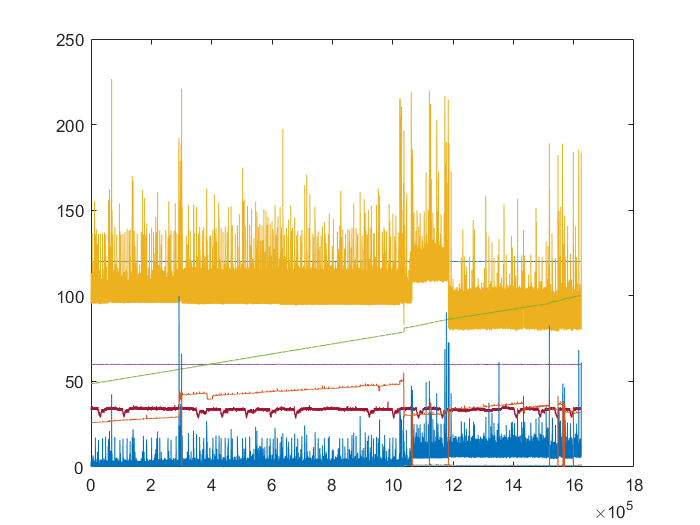

plot(data)